# Example 3.1: Subdomains and Logic

Note: this script reproduces Example 3.1 (Section 3.1) of **Statistics for Chemical Engineers**: events of the Gibbs reactor defined by subdomains of pressure and conversion. Victor Z UW-Madison, 2020 gibbs reactor example (subdomains)

clc; clear all; close all hidden;

## Data

create data set

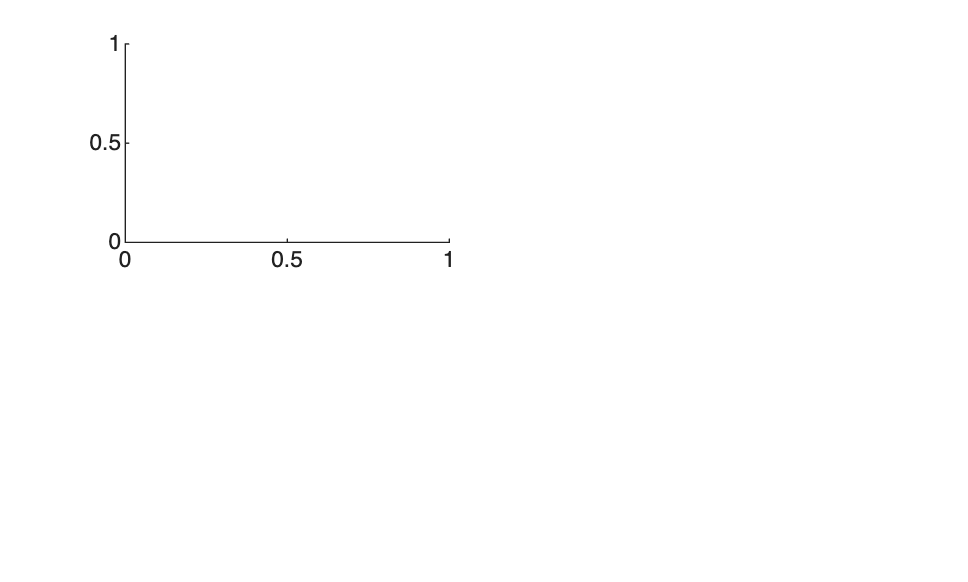

load ('./Data/gibbs_hightemp_class.dat')
datahigh=gibbs_hightemp_class;
data=[datahigh];
datan=data;
n=length(datan);

% corrupt data with noise to hide pattern 
rng(1); % For reproducibility 
P = datan(:,2)+randn(n,1); % pressure 
C = datan(:,3)+randn(n,1)*0.05; % conversion


figure(1)
subplot(2,2,1)

## Event 1

draw domain for P in [100 200]

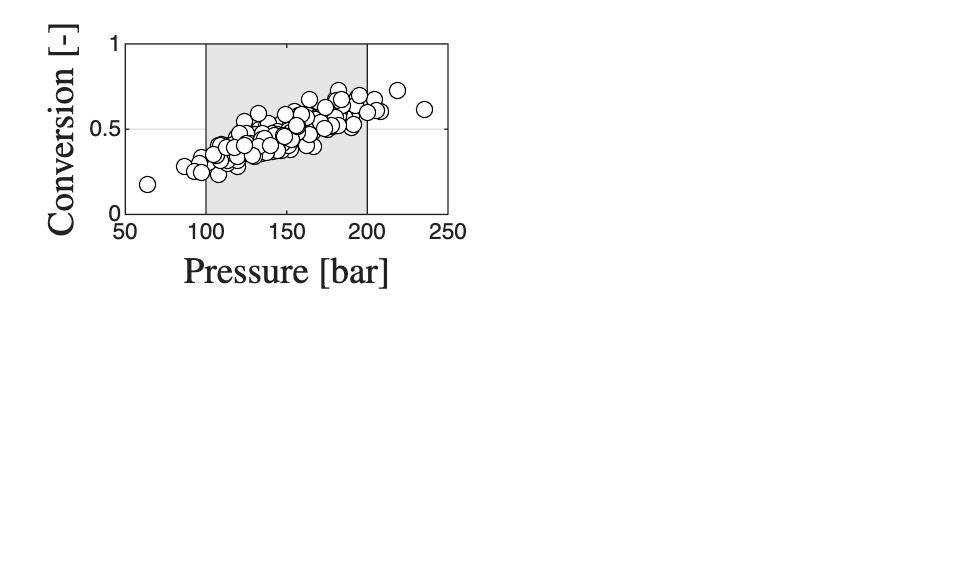

fill([100 200 200 100], [0 0 1 1],[0.9 0.9 0.9]);
hold on
scatter(P,C,'blacko','MarkerFaceColor','w')
grid on
xlabel('$\textrm{Pressure [bar]}$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Conversion [-]}$','Interpreter','latex','FontSize',14)
box on
hold on
axis([50 250 0 1])

## Event 2

draw domain for P in [100,200] and C in <= 0.5

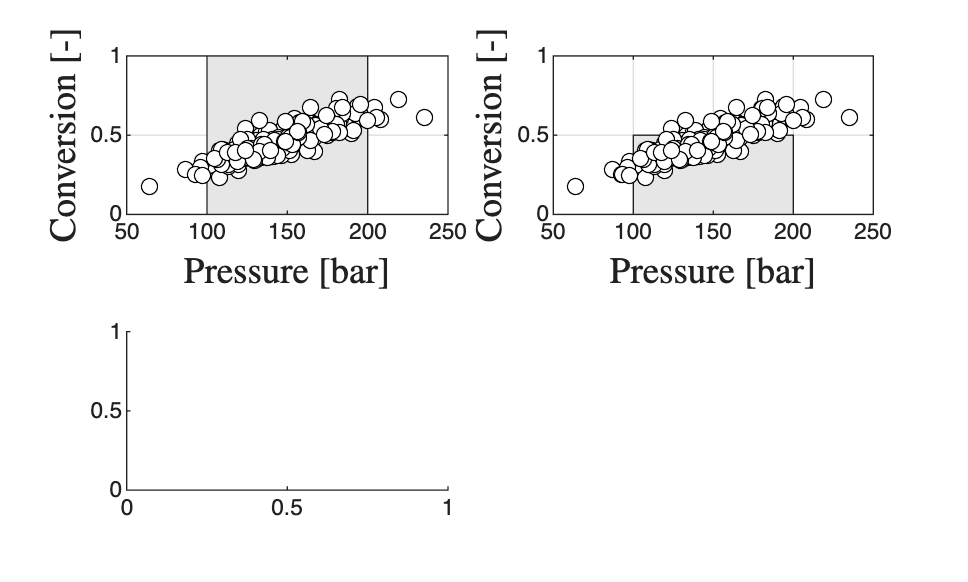

subplot(2,2,2)
fill([100 200 200 100], [0 0 0.5 0.5], [0.9 0.9 0.9]);
hold on
scatter(P,C,'blacko','MarkerFaceColor','w')
grid on
xlabel('$\textrm{Pressure [bar]}$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Conversion [-]}$','Interpreter','latex','FontSize',14)
box on
hold on
axis([50 250 0 1])

subplot(2,2,3)

## Event 3

draw domain for P [100 or P](http://=)=200 and C in >= 0.5

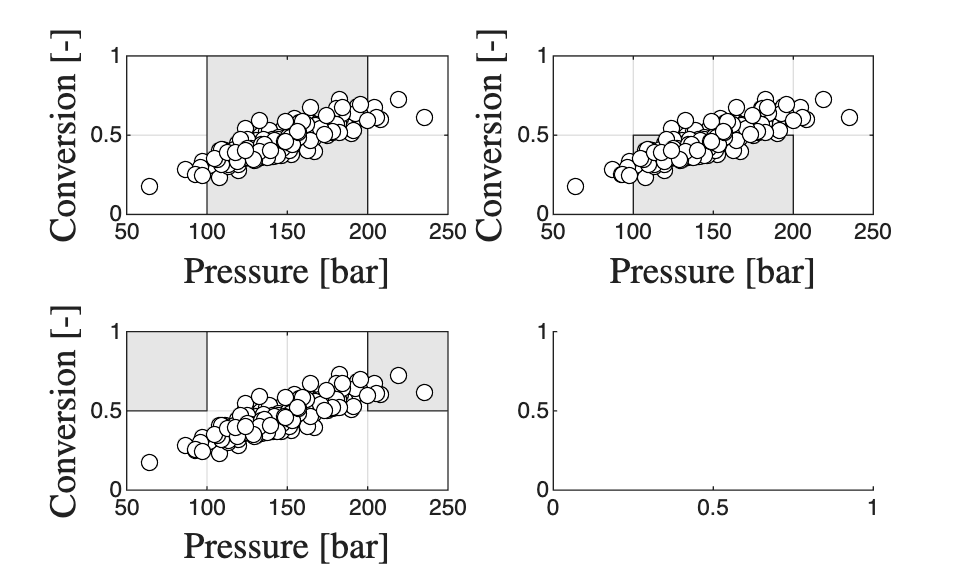

fill([0 100 100 0], [0.5 0.5 1 1], [0.9 0.9 0.9]);
hold on
fill([200 250 250 200], [0.5 0.5 1 1], [0.9 0.9 0.9]);
hold on
scatter(P,C,'blacko','MarkerFaceColor','w')
grid on
xlabel('$\textrm{Pressure [bar]}$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Conversion [-]}$','Interpreter','latex','FontSize',14)
box on
hold on
axis([50 250 0 1])

subplot(2,2,4)

## Event 4

draw domain for P [100 and P](http://=)=200 and C in >= 0.5 (this is impossible)

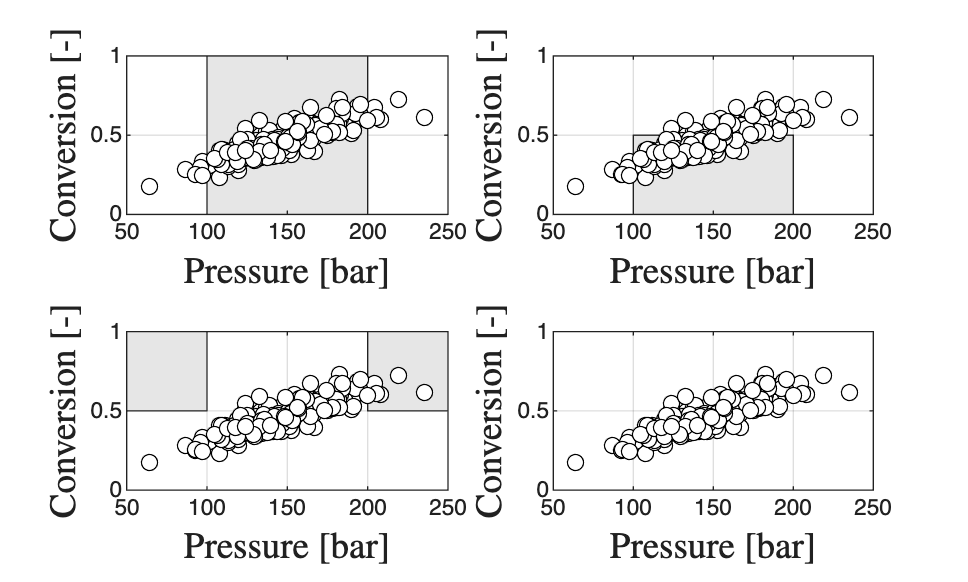

scatter(P,C,'blacko','MarkerFaceColor','w')
grid on
xlabel('$\textrm{Pressure [bar]}$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Conversion [-]}$','Interpreter','latex','FontSize',14)
box on
axis([50 250 0 1])
print -depsc ch3_gibbs_subdomains.eps

## Note

As in the book, the probability of each event is the fraction of realizations in its subdomain; the last event has probability zero because its subdomain is empty.